# **RT-QIBC**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
m = matfile([dataDir filesep 'gemDbox_alldata.mat']);

dat = m.S(1,3);
dat = dat{1};
gate = m.gates_all(1,3);
gate = gate{1};
medEdU = m.medEdU_all(1,3);

**Plot Cdt1 levels DMSO short**

ans =    209   242   238   215   123   564   407   226   147   170   189   228   184   179   180   209


ans = 123

ans = 3710

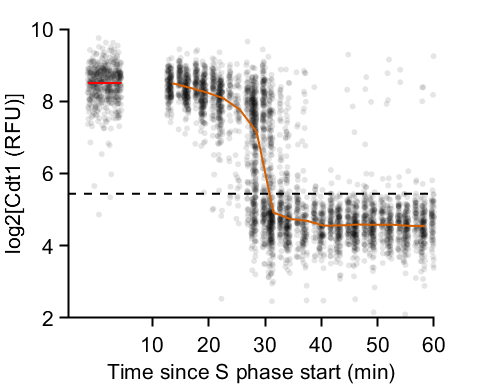

conds=[1];
poiAligned=3;
offset=-1;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);

gateVals = {{}};
rangeVals = {{}};
rng(1)
% range = linspace(0,4,10);
edges = (.2:1/dat(1).framesPerHr:1);
midpoints = edges + (edges(2) -edges(1))/2;
midpoints = midpoints(1:end-1);

for i=1:length(conds)
    ind= gate_vals(dat(conds(i)), gateVals{i}, rangeVals{i}) & dat(conds(i)).POI_time(:,poiAligned) <=1;
    
    xdata = dat(conds(i)).POI_time(ind,poiAligned);
    ydata = [];
    ydata(:, 1) = log2(dat(conds(i)).YFP1(ind));
    ydata(:, 2) = log2(dat(conds(i)).YFP2(ind));
    ydata(:, 3) = log2(dat(conds(i)).FarRed1(ind)) ;
    
    
    threshs ={{log2(gate.YFP1_S(2)), -1}, {gate.YFP2_G1(2), 1}, {gate.FarRed1_G1(2), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',edges);
    
    binData(1).numCells
    min(binData(1).numCells)
    length(xdata)
    %%% Get G1 levels
    inds = dat(conds(i)).POI_time(:,1) <= 2 & dat(conds(i)).POI_time(:,1) > 1 &...
        isnan(dat(conds(i)).POI(:,3));
    g1Y = log2(dat(conds(i)).YFP1(inds));
    subsinds = randsample(length(g1Y),500);
    g1Y = g1Y(subsinds);
    jitterX = rand(size(g1Y))*.1 -.025;
    
    
    %%% Plot black and colored by Cdt1 levels
    figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
    hold on
    scatter(xdata*60,ydata(:,1),20,'k','filled','MarkerFaceAlpha',.1);
    plot(midpoints*60,binData(1).median,'LineWidth',1.5,'Color',[213 94 0]/255);
    ylim([2 10]);
    xlim([-5 60]);
    xticks([10:10:60])
    ylabel('log2[Cdt1 (RFU)]');xlabel('Time since S phase start (min)');
%     title(dat(1).conditions{conds(i),1});
    h=hline(log2([gate.YFP1_S(2)]),'k--');
    scatter(jitterX*60,g1Y,20,'k','filled','MarkerFaceAlpha',.1);
        plot([-.025 .075]*60,log2([gate.YFP1_G1(2) gate.YFP1_G1(2)]),'r')
%     pbaspect([1.20 1 1])
    print_pdf([pwd() '\Figs\C206_Cdt1_time_short.pdf'])

   
end

## Compare geminin levels 

%%% 1-2 hr post mitosis
conds=[1 2];
figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
g1 = {};
for i=1:length(conds)
    c = conds(i);
    inds = dat(c).POI_time(:,1) > 1 &  dat(c).POI_time(:,1) <= 2 ;
    g1{i} = dat(c).YFP2(inds);
    g1{i}(g1{i}< 1) = [];
    g1{i} = log2(g1{i});
end

% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21.8 & dat(condition).allFarRed1 > 2^8 & dat(condition).allFarRed1 < 2^11;
g1{3} = dat(condition).allYFP2(ind);
g1{3}(g1{3}< 1) = [];
g1{3} = log2(g1{3});

% nhist(g1, 'npoints',   'samebins', 'noerror','legend',{dat(1).conditions{conds,1}, 'G2'},'fsize',16)
% title([dat(1).experiment ' G1 phase'])
% xlabel('log2(GMNN) (AU)')
% pbaspect([1 1 1])
% print_pdf([pwd() '\Figs\C206_gmnn_over_hist_G1.pdf'])

% g1dmso = g1{1};
% g1dox = g1{2};
% g1dmso = g1dmso(~isnan(g1dmso));
% g1dox = g1dox(~isnan(g1dox));
% [h,p,ci,stats] = ttest2(g1dmso,g1dox)

%%% S phase start
conds=[1 2];
figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
s = {};
for i=1:length(conds)
    c = conds(i);
    inds = dat(c).POI_time(:,3) <= .5;
    s{i} = dat(c).YFP2(inds);
    s{i}(s{i}< 1) = [];
    s{i} = log2(s{i});
end

% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21.8 & dat(condition).allFarRed1 > 2^8 & dat(condition).allFarRed1 < 2^11;
s{3} = dat(condition).allYFP2(ind);
s{3}(s{3}< 1) = [];
s{3} = log2(s{3});

% nhist(s, 'npoints',   'samebins', 'noerror','legend',{dat(1).conditions{conds,1}, 'G2'},'fsize',16)
% title([dat(1).experiment ' S phase'])
% xlabel('log2(GMNN) (AU)')
% pbaspect([1 1 1])
% print_pdf([pwd() '\Figs\C206_gmnn_over_hist_S.pdf'])

% sdmso = s{1};
% sdox = s{2};
% sdmso = sdmso(~isnan(sdmso));
% sdox = sdox(~isnan(sdox));
% [h,p,ci,stats] = ttest2(sdmso,sdox)

rng(1)
all_cell = [g1(1:2) s]';
all_cell = cellfun(@(x) randsample(x,min([2000 length(x)])),all_cell,'UniformOutput',false);
ally = cell2mat(all_cell);
group = [];    
for i=1:length(all_cell)
    group = [group; i*ones(size(all_cell{i}))];
    size(all_cell{i})
end

ans =         2000           1


ans =         2000           1


ans =         1592           1


ans =         1316           1


ans =         1855           1



inds = ally > 4;
ally = ally(inds);
group = group(inds);

group_list = 1:max(group);
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1 DMSO','G1 DOX','early S DMSO','early S DOX','G2'},'xValues',xkey,'distWidth',.8);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [cols([1 2 1 2],:);[0 0 0]];
set(h{1},{'FaceColor'},{cols(1,:),cols(2,:),cols(1,:),cols(2,:),[.8 .8 .8]}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.2);
ylabel('log2[Geminin (RFU)]')
% ylim([0 2.25])
% xtickangle(45)
xticks([xkey(1:2:length(xkey)-1)+.5 6])
xticklabels({'G1','S','G2'})
axis square
print_pdf([pwd() '\Figs\C206_gmnn_compare_scatter_overexpress.pdf'])

**stat test EdU comparison DMSO/DOX zeroed**

Gate for early mitosis, first .3 hrs, high/low geminin


rng(1)
xval = 'YFP1';
yval = 'YFP2';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = dat(condition).(yval) - gate.YFP2_G1(1);

inds = dat(condition).POI_time(:,1) <= 1.5 & dat(condition).POI_time(:,1) >= 1 & ...
    dat(condition).FarRed1 < gate.FarRed1_G1(2) & dat(condition).YFP1 > 2^7  & dat(condition).dna < 2^21.5;
ydata = ydata(inds);

inds = randsample(length(ydata),600);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  1;
ydata = dat(condition).(yval) - gate.YFP2_G1(1);

inds = dat(condition).POI_time(:,3) <= .5 & dat(condition).FarRed1 < 2^10 & dat(condition).dna < 2^21.5 ...
    & dat(condition).YFP1 > 2*gate.YFP1_S(2);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 1;
ind = dat(condition).allDNA > 2^21.8 & dat(condition).allFarRed1 > 2^9 ...
    & dat(condition).allFarRed1 < 2^11 & dat(condition).allYFP1 < gate.YFP1_G1(1);
ydata = dat(condition).allYFP2(ind) - gate.YFP2_G1(1);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];

% ally = ally - median(ally(group ==1));
ally = ally/median(ally(group == 3));
median(ally(group == 2))

ans = 0.0922


test = cellfun(@(x) x/median(test{3}),test,'UniformOutput',false);
cellfun(@median,test)

ans =    -0.0053    0.0922    1.0000


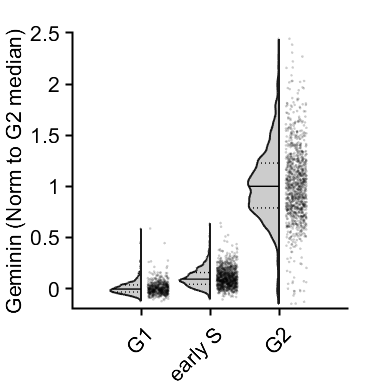


% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% notBoxPlot((ally),group)

% jit = 0.5*(rand(size(group))-0.5);
% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% scatter(group+jit, (ally), 10,'k','filled','MarkerFaceAlpha',.2);z
% xlim([0 max(group)+1])
% 
% figure('Units', 'Inches', 'Position', [0, 0, 5, 4])
% violinPlot((ally),'groups',group, 'showMM',5,'histOpt',1,'divFactor',1.5)

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.2);
ylabel('Geminin (Norm to G2 median)')
ylim([-0.2 2.5])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\C206_gmnn_compare_scatter_zero.pdf'])

test

test = 1×3 cell array
    {600×1 double}    {1051×1 double}    {1063×1 double}


figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on

points = [.098 .1038 .0922; 1 1 1]';
mean_points = mean(points)

mean_points =     0.0980    1.0000


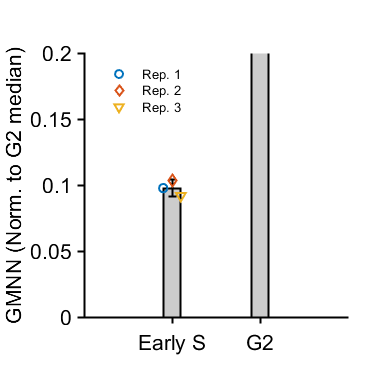

sem_points = std(points)/sqrt(3);
bar([1 2],mean(points),.2,'FaceColor',[.8 .8 .8],'LineWidth',1.5)
% errorbar(1,mean_dmso,neg,pos,'k+','LineWidth',1.5)
errorbar(1,mean_points(1),2*sem_points(1),'k+','LineWidth',1.5)
shapes = ['odv'];
jit = .1*[-1 0 1];
set(gca,'ColorOrderIndex',1)
s=[];
for i=1:size(points,2)
    for j = 1:size(points,1)
        s(j) = scatter(i+jit(j),points(j,i),40,shapes(j),'LineWidth',1.5);
    end
    set(gca,'ColorOrderIndex',1)
end
pbaspect([1 1 1])
legend(s,{'Rep. 1','Rep. 2','Rep. 3'},'FontSize',10,'Box','off','Location','northwest')
ylabel('GMNN (Norm. to G2 median)')
ylim([0 .2])
xticks([1 2])
xlim([0 3])
xticklabels({'Early S','G2'})
print_pdf([pwd() '\Figs\gmnn_corr_bar.pdf'])


[h,p,ci,stats] = ttest(points(:,1))

h = 1

p = 0.0012

ci =     0.0836
    0.1124


stats = struct with fields:
    tstat: 29.2657
       df: 2
       sd: 0.0058
